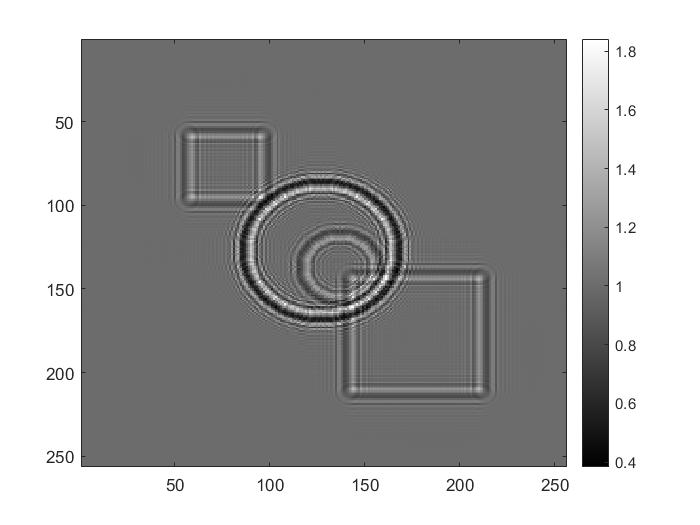

% Citation for this code and algorithm:
% Paganin D, Mayo S C, Gureyev T E, et al.
% "Simultaneous phase and amplitude extraction from a single defocused image of a homogeneous object",
% Journal of microscopy, 2002, 206(1): 33-40.
% This code also references from Diivanand Ramalingam, 2014
%%%%%%%%%%%%%%%%%%%%%

clear all
clf

% Import data
IntensityDetector = h5read('TIE_exercise.h5','/data/IntensityDetector');

% Parameters
R2 = 0.2;
delta = 1.5e-6;
mu = 264;
Iin = 1;
ps = 1e-6;
M = 256;

% Set up axis 
fx = 1/ps*((2*pi*(0:255)/256)-pi)/(2*pi);
fy = 1/ps*((2*pi*(0:255)/256)-pi)/(2*pi);

[Fx,Fy] = meshgrid(fx,fy);
Fx = transpose(Fx);
Fy = transpose(Fy);

%Equation(10)
I2fft = fftshift(fft2(IntensityDetector));
I2fftScaled = (I2fft / Iin) * mu;
denominator = (R2 * delta) * (Fx.^2 + Fy.^2) + mu;

E = I2fftScaled ./ denominator ;
ProjectedThickness = -(1/mu) * log(real(ifft2(ifftshift(E))));

%Images
imagesc(IntensityDetector);
colormap gray;
colorbar;

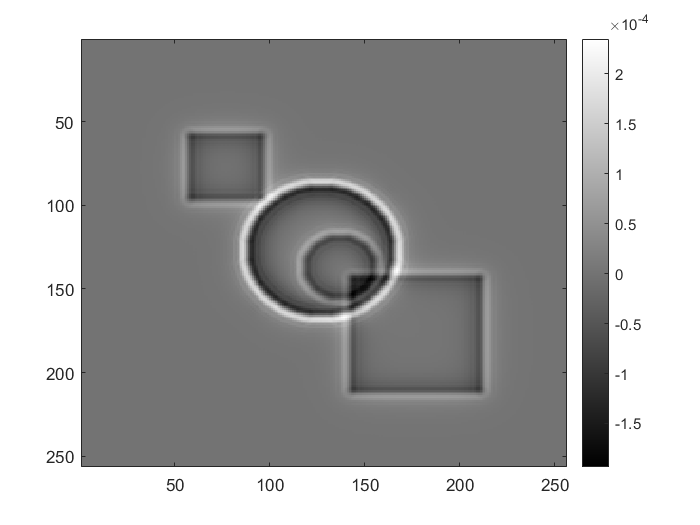

title("image of intensity detector")
imagesc(ProjectedThickness);
colormap gray;
colorbar;

title("image of projected thickness")